# **生成路网与交通流图数据**

**Komasa Qi,** 2023210322, **清华大学车辆与运载学院**, 2025年12月20日

## 1 将路网数据提取为图结构

% 首先进行仿真
% COMPASS_Run_Highway % 默认已经仿真，此处不进行

下面查看一下我们要操作的数据对象类型

entity_dict

entity_dict =   具有 5207 个条目的 dictionary (string ⟼ cell):

    ":10137989002_0_0"                                                ⟼ {1×1 Lane_SUMO}
    ":10137989002_0"                                                  ⟼ {1×1 Edge_SUMO}
    ":10137989002_1_0"                                                ⟼ {1×1 Lane_SUMO}
    ":10137989002_1"                                                  ⟼ {1×1 Edge_SUMO}
    ":10137989003_0_0"                                                ⟼ {1×1 Lane_SUMO}
    ":10137989003_0"                                                  ⟼ {1×1 Edge_SUMO}
    ":10137989003_1_0"                                                ⟼ {1×1 Lane_SUMO}
    ":10137989003_1"                                                  ⟼ {1×1 Edge_SUMO}
    ":10137989007_0_0"                                                ⟼ {1×1 Lane_SUMO}
    ":10137989007_0"                             

可以看到字典当中包含了**Edge_SUMO**、**Lane_SUMO**和**Junction_SUMO**三种类型的实体。路网的主要组成是Edge,一条Edge相当于一条单向的路，其可能包含1~N条车道。Edge和Lane的ID如果前面第一个字符是“:”，说明该边/车道是在交叉口Junction内部的。

entity_dict{'3249288485'}, entity_dict{"cluster_11850343062_11850441361_11850441362_7116958741"} % Junction

ans =   Junction_SUMO - 属性:

          id: '3249288485'
         pos: []
        type: 'priority'
        name: []
           x: 59881
           y: 8.6688e+04
    incLanes: {4×1 cell}
    intLanes: {4×1 cell}
       shape: [10×2 double]


ans =   Junction_SUMO - 属性:

          id: 'cluster_11850343062_11850441361_11850441362_7116958741'
         pos: []
        type: 'priority'
        name: []
           x: 4.2576e+04
           y: 1.0259e+05
    incLanes: {3×1 cell}
    intLanes: {5×1 cell}
       shape: [13×2 double]


entity_dict{'761727441#1'}, entity_dict{':cluster4175844450_8953436696_0'} % Edge

ans =   Edge_SUMO - 属性:

         id: '761727441#1'
       from: '4907013343'
         to: '4907013342'
    laneNum: 3


ans =   Edge_SUMO - 属性:

         id: ':cluster4175844450_8953436696_0'
       from: []
         to: []
    laneNum: 2


entity_dict{'761727441#1_0'},entity_dict{':cluster4175844450_8953436696_0_0'} % Lane

ans =   Lane_SUMO - 属性:

        id: '761727441#1_0'
     index: 0
     speed: 39.4400
    length: 850.3300
     shape: [4×2 double]
     width: 3.2000


ans =   Lane_SUMO - 属性:

        id: ':cluster4175844450_8953436696_0_0'
     index: 0
     speed: 25
    length: 8.9400
     shape: [5×2 double]
     width: 3.2000


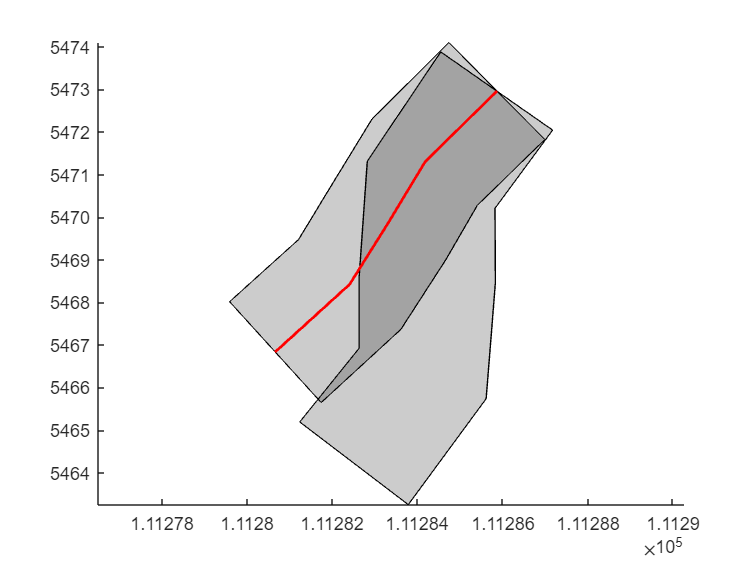

theEdgeID = ':cluster4175844450_8953436696_0';
theLaneID = ':cluster4175844450_8953436696_0_0';
figure(5)
clf
plotSUMOentity(entity_dict,{theEdgeID},5);
hold on
plot(entity_dict{theLaneID}.shape(:,1),entity_dict{theLaneID}.shape(:,2),'Color','r','LineWidth',1.5)
hold off

connection_dict{theEdgeID},connection_dict{theEdgeID}.connections{1},connection_dict{theEdgeID}.connections{2}

ans = 包含以下字段的 struct :
    connection_num: 2
       connections: {[1×1 Connection_SUMO]  [1×1 Connection_SUMO]  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []  []}


ans =   Connection_SUMO - 属性:

        from: ':cluster4175844450_8953436696_0'
          to: '1084259319#0'
    fromLane: 0
      toLane: 0
         via: []
         dir: 's'
       state: 'M'


ans =   Connection_SUMO - 属性:

        from: ':cluster4175844450_8953436696_0'
          to: '1084259319#0'
    fromLane: 1
      toLane: 1
         via: []
         dir: 's'
       state: 'M'


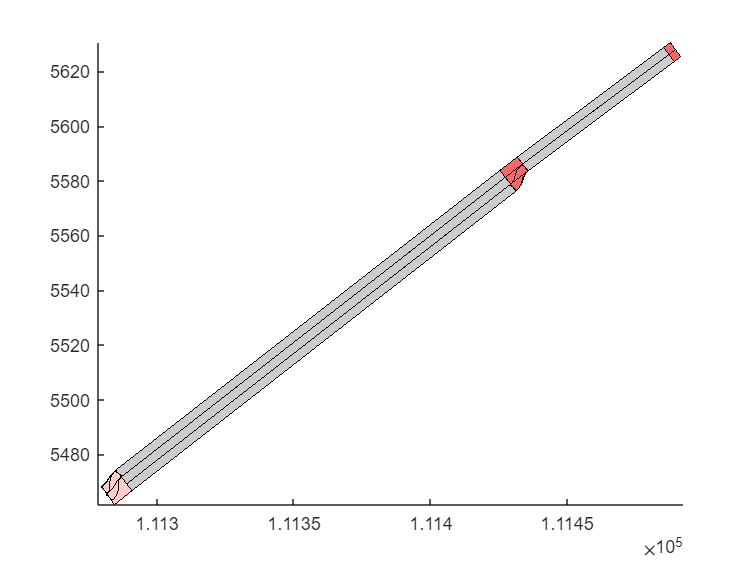

ans =   具有 4 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "225384152#1_0"   ⟼ 1×1 Patch
    "225384152#1_1"   ⟼ 1×1 Patch
    ":2341663163_0_0" ⟼ 1×1 Patch
    ":2341663163_1_0" ⟼ 1×1 Patch


ans =   具有 1 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "2341663163" ⟼ 1×1 Patch


ans =   具有 4 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "225384152#1_0"   ⟼ 1×1 Patch
    "225384152#1_1"   ⟼ 1×1 Patch
    ":2341663163_0_0" ⟼ 1×1 Patch
    ":2341663163_1_0" ⟼ 1×1 Patch


ans =   具有 1 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "2341663163" ⟼ 1×1 Patch


ans =   具有 10 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "225384152#1_0"   ⟼ 1×1 Patch
    "225384152#1_1"   ⟼ 1×1 Patch
    "416903036_0"     ⟼ 1×1 Patch
    "416903036_1"     ⟼ 1×1 Patch
    "416903036_2"     ⟼ 1×1 Patch
    ":2341663161_0_0" ⟼ 1×1 Patch
    ":2341663161_0_1" ⟼ 1×1 Patch
    ":2341663161_0_2" ⟼ 1×1 Patch
    ":2341663163_0_0" ⟼ 1×1 Patch
    ":2341663163_1_0" ⟼ 1×1 Patch


ans =   具有 2 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "2341663161" ⟼ 1×1 Patch
    "2341663163" ⟼ 1×1 Patch


ans =   具有 4 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "225384152#1_0"   ⟼ 1×1 Patch
    "225384152#1_1"   ⟼ 1×1 Patch
    ":2341663163_0_0" ⟼ 1×1 Patch
    ":2341663163_1_0" ⟼ 1×1 Patch


ans =   具有 1 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "2341663163" ⟼ 1×1 Patch


ans =   具有 4 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "225384152#1_0"   ⟼ 1×1 Patch
    "225384152#1_1"   ⟼ 1×1 Patch
    ":2341663163_0_0" ⟼ 1×1 Patch
    ":2341663163_1_0" ⟼ 1×1 Patch


ans =   具有 1 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "2341663163" ⟼ 1×1 Patch


ans =   具有 10 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "225384152#1_0"   ⟼ 1×1 Patch
    "225384152#1_1"   ⟼ 1×1 Patch
    "416903036_0"     ⟼ 1×1 Patch
    "416903036_1"     ⟼ 1×1 Patch
    "416903036_2"     ⟼ 1×1 Patch
    ":2341663161_0_0" ⟼ 1×1 Patch
    ":2341663161_0_1" ⟼ 1×1 Patch
    ":2341663161_0_2" ⟼ 1×1 Patch
    ":2341663163_0_0" ⟼ 1×1 Patch
    ":2341663163_1_0" ⟼ 1×1 Patch


ans =   具有 2 个条目的 dictionary (string ⟼ matlab.graphics.Graphics):

    "2341663161" ⟼ 1×1 Patch
    "2341663163" ⟼ 1×1 Patch


edgeList = 6×1 cell 数组
    {'225384152#1'                    }
    {'416903036'                      }
    {':2341663161_0'                  }
    {':2341663163_0'                  }
    {':2341663163_1'                  }
    {':cluster4175844450_8953436696_0'}


junctionList = 3×1 cell 数组
    {'2341663161'                  }
    {'2341663163'                  }
    {'cluster4175844450_8953436696'}


figure(7)
clf
[edgeList,junctionList] = plotNLevelRoadNet(entity_dict,connection_dict,theEdgeID,3,7,'2D')

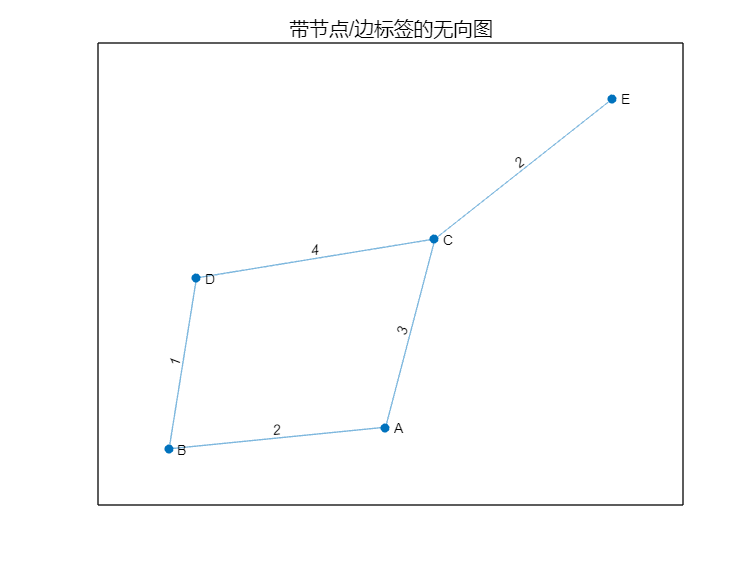

% 创建带权重的无向图
src = {'A', 'A', 'B', 'C', 'C'};
tgt = {'B', 'C', 'D', 'D', 'E'};
weights = [2, 3, 1, 4, 2];
G_undir = graph(src, tgt, weights);

% 可视化并显示节点名称、边权重
figure;
plot(G_undir, ...
    'NodeLabel', G_undir.Nodes.Name, ... % 显示节点标签（默认节点名称）
    'EdgeLabel', G_undir.Edges.Weight ... % 显示边标签（边权重）
    ); % 边标签字体大小
title('带节点/边标签的无向图');

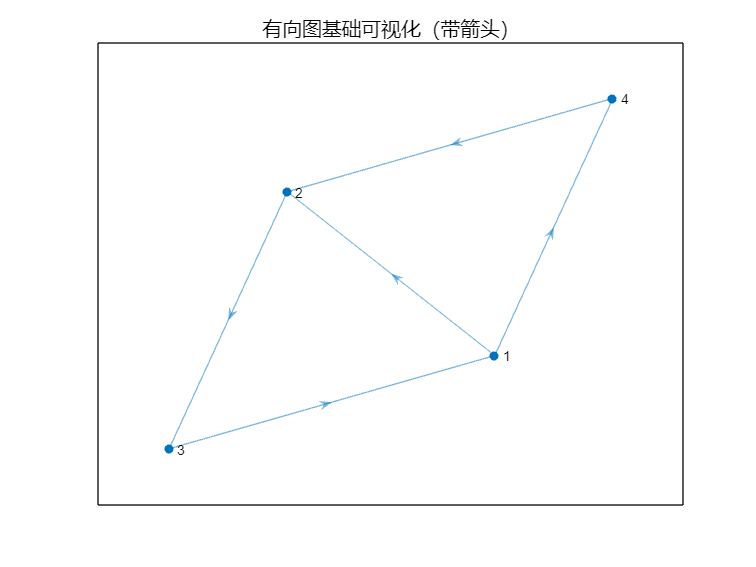

% 创建带权重的有向图
src_dir = [1, 2, 3, 1, 4];
tgt_dir = [2, 3, 1, 4, 2];
weights_dir = [2.1, 1.8, 3.5, 4.2, 2.9];
G_dir = digraph(src_dir, tgt_dir, weights_dir);

% 基础可视化
figure;
h = plot(G_dir);
title('有向图基础可视化（带箭头）');

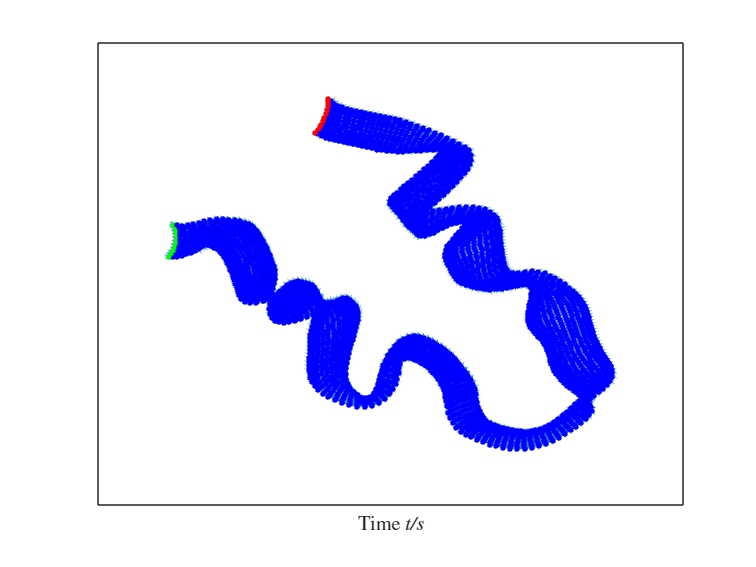

edgeID = ego.edgeID;
G_edge = genEdgeGraph(edgeID);
color_map = dictionary(-1,{[1 0 0]},0,{[0 0 1]},1,{[0 1 0]});
nodes_colors = arrayfun(@(c) color_map{c}, G_edge.Nodes.free_ends_feat,'UniformOutput',false);
figure,plot(G_edge,'Layout','force','NodeColor',reshape([nodes_colors{:}],3,[])')

edgeID = ego.edgeID;
G_edge = genEdgeGraph(edgeID);
color_map2 = dictionary(4,{[1 0 0]},0,{[1 1 0]},1,{[0 0 1]},2,{[0 1 0]});
nodes_colors = arrayfun(@(c) color_map2{c}, round(G_edge.Nodes.nodes_type_feat*2),'UniformOutput',false);
figure,plot(G_edge,'Layout','force','NodeColor',reshape([nodes_colors{:}],3,[])')

G1 = genEdgeGraph(edgeID,[],[],[],true);
G2 = genEdgeGraph('96615334#0-AddedOffRampEdge',[],[],[],true);
G_comb = seamSubGraphs({G1},{G2})
color_map2 = dictionary(20,{[1 0 0]},0,{[1 1 0]},5,{[0 0 1]},10,{[0 1 0]},1,{[1,0,1]});
nodes_colors = arrayfun(@(c) color_map2{c}, round(G_comb.Nodes.nodes_type_feat*10),'UniformOutput',false);
% figure,plot(G_comb,'Layout','force','NodeColor',reshape([nodes_colors{:}],3,[])')
figure,plot(G_comb,'XData',G_comb.Nodes.nodes_pos(:,1),'YData',G_comb.Nodes.nodes_pos(:,2),'NodeColor',reshape([nodes_colors{:}],3,[])')